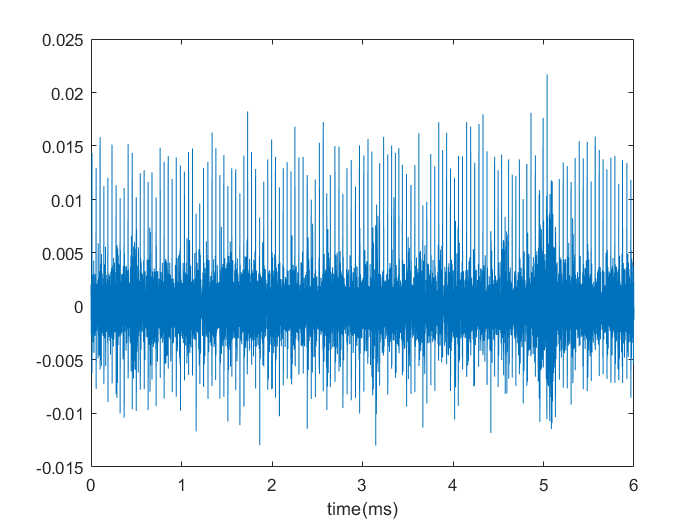

f = load('ecg.mat');
v = f.ecg;
b = reshape(v, [1,60001]);
t = linspace(0, 6, 60001);

plot(t,b)
xlabel("time(ms)");

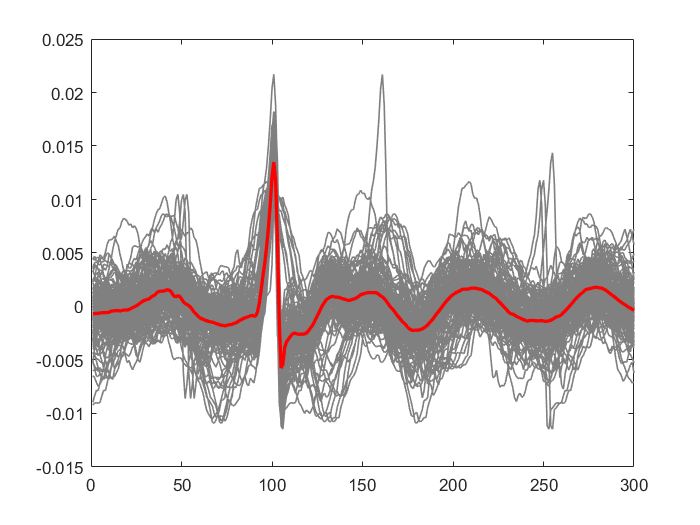


b(b < 0.01) = 0;

[val, idx] = findpeaks(b);
z = zeros(length(idx), 300);
for i = 1:length(idx)
    z(i, :) = v(idx(i)-100: idx(i)+199);
end

avg = mean(z);

 
plot(z', 'Color', [0.5, 0.5,0.5,0.5], 'linewidth', 1)
hold on
plot(avg, 'Color', 'Red', 'linewidth', 2)
hold off